## Calculo del ITD de Woodworth

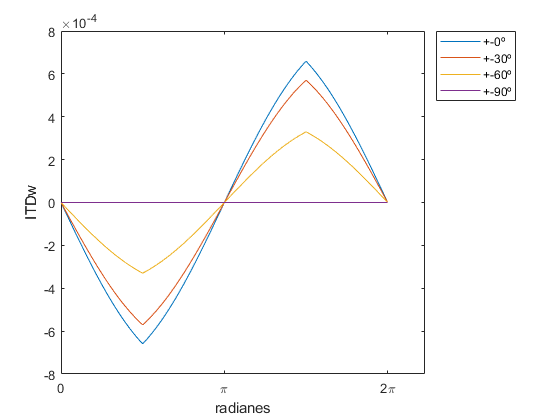

%clear; %a; W; x;                  %clear the values
a = 0:0.01:2*pi;   
rtograd = a * 180/pi;
W(length(a)) = 0;
P(length(a)) = 0;
Q(length(a)) = 0;
R(length(a)) = 0;
for x=1:length(a)               %Executes the program
W(x) = ITDw(0.088, 343.2, a(x),0);
P(x) = ITDw(0.088, 343.2, a(x),30);
Q(x) = ITDw(0.088, 343.2, a(x),60);
R(x) = ITDw(0.088, 343.2, a(x),90);
end
%plot(a,W)                      %Plot the drawing
%hold on;
plot(a,W); hold on; plot(a,P); plot(a,Q); plot(a,R); legend('+-0º','+-30º','+-60º','+-90º'); xlabel('radianes'); ylabel('ITDw'); xticks([0 pi 2*pi]); xticklabels({'0','\pi','2\pi'})
hold off;

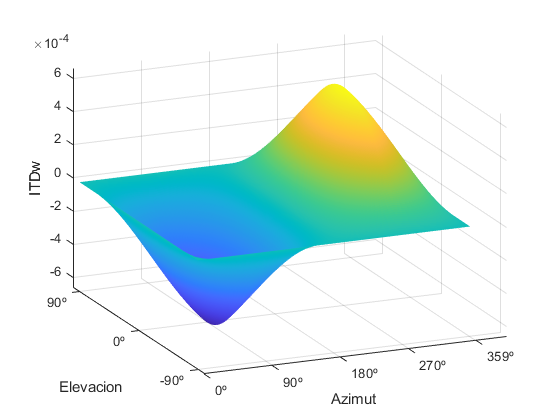

b = -90:90;
T(length(rtograd), length(b)) = 0;
for x=1:length(rtograd)   %Executes the program
    for y = 1:length(b)
        T(x,y) = ITDw(0.088,343.2, a(x),b(y));
    end
end

surf(b,rtograd,T,'EdgeColor',"none"); xlabel('Elevacion'); ylabel('Azimut'); zlabel('ITDw'); yticks([0 90 180 270 359]); yticklabels({'0º','90º','180º','270º','359º'});
xticks([-90 0 90]); xticklabels({'90º','0º','-90º'});
hold off;

## Calculo ITD de archivos SOFA

addpath('VERSION ANTERIOR APIMO\');
addpath('VERSION ANTERIOR APIMO\API_MO');
addpath('src\');
SOFAstart;
addpath('VERSION ANTERIOR APIMO\HRTFs\SADIE\D1_HRIR_SOFA')
hrtf = SOFAload('D1_44K_16bit_256tap_FIR_SOFA.sofa');
ITDww = hrtf.SourcePosition; %ITD woodworth
Umbral = 0.1:0.01:0.5;
clear ITDt;
ITDt(length(hrtf.SourcePosition),length(Umbral)) = 0;


for x = 1:length(hrtf.SourcePosition(:,1))
    for i=1:length(Umbral)
        ITDt(x,i) = MetodoUmbral(hrtf,ITDww(x,1), ITDww(x,2), 3000, Umbral(i));
    end

    ITDww(x,3) = ITDw(0.088,343.2,deg2rad(ITDww(x,1)),ITDww(x,2));
end

## Visualización de los ITD

% rtograd = a * 180/pi;
% mesh(rtograd,b,T','EdgeColor',"#0072BD",'FaceAlpha',1),xlabel('radianes'); ylabel('Elevacion');
%Reordenar(ITDww(:,1),ITDww(:,2),ITDww(:,3));
m = unique(ITDww(:,1));
n = unique(ITDww(:,2));
datos = nan(length(m),length(n));
for i = 1:length(ITDww)
    datos(m==ITDww(i,1),n==ITDww(i,2)) = ITDww(i,3);
end
datos(:,n==-90) = 0; datos(:,n==90) = 0;
surf(m',n',datos','EdgeColor',"#0072BD",'FaceAlpha',1), xlabel('radianes'); ylabel('Elevacion');
hold on;
Reordenar(ITDww(:,1),ITDww(:,2),ITDt(:,10));
hold off;
%Reordenar(ITDww(:,1),ITDww(:,2),ITDww(:,3));

## Imagen de la señal pre y post filtrada (lado derecho a 0º)

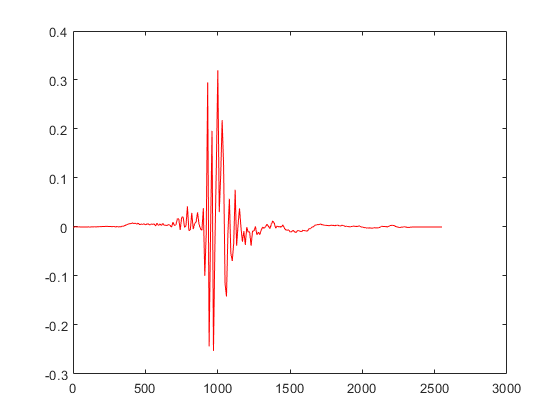

Pos = [];
fs = hrtf.Data.SamplingRate;
PosE = find(abs(hrtf.SourcePosition(:,2)) < 10^-10, 400); %posicion elevacion. Busco las 400 muestras que hay
PosA = find(abs(hrtf.SourcePosition(:,1)) == 0, 50); %| abs(hrtf.SourcePosition(:,1)) == 90 | abs(hrtf.SourcePosition(:,1)) == 180 | abs(hrtf.SourcePosition(:,1)) == 270, 100);
PosE = PosE'; %Las convierto de columnas a filas
PosA = PosA';
%L2 = squeeze(hrtf.Data.IR(Pos,2,:));
%plot(x,L2, 'b')
%Comparo las posiciones y me quedo con las que se repiten
for x = 1:length(PosA)
    for y = 1:length(PosE)
        if PosA(x) == PosE(y)
            Pos = [Pos PosE(y)];
        end
    end
end
A = reshape(hrtf.Data.IR(Pos,1,:), [1, length(hrtf.Data.IR(Pos,1,:))]); %%convertimos este vector en 1x512
B = reshape(hrtf.Data.IR(Pos,2,:), [1, length(hrtf.Data.IR(Pos,2,:))]);

%% Oversampling
OS = 10; % Oversampling factor
ta = 0:1/fs:(length(A)-1)/fs;
ty = 0:1/(OS*fs):(length(A)-1)/(fs);
R = interp1(ta,B,ty);%% Oversampling x10
x = 1:length(R);
figure;
plot(x,R,'r');
hold off;

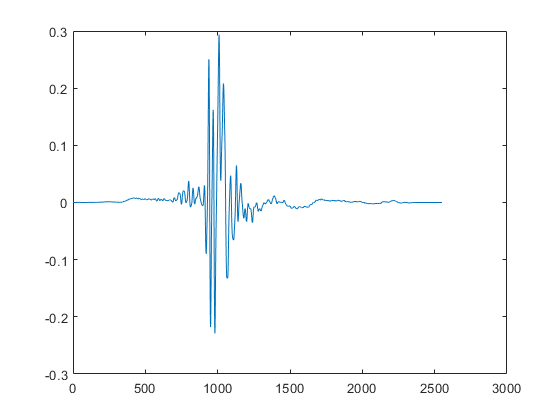

    
MetodoUmbral(hrtf, hrtf.SourcePosition(Pos,1), hrtf.SourcePosition(Pos,2), 5000, 0.22);
hold off;

## Calculo de las diferencias y del valor del umbral con menor ITD

diffITD = [];
format long;
nr = 0; nc = 0;
[nr,nc] = size(ITDt);
diffITD(nr,nc) = 0;
diffITD = ITDt1-ITDww1(:,3);
SUM(length(nc)) = 0;
for i = 1:nc
    SUM(i) = sum(diffITD(:,i).^2);
end
[ans,mu] = min(SUM)

ans =      2.585309974514918e-05


mu =     16


Umbral(SUM==min(SUM))

ans =    0.250000000000000


## Comparativa de los 3 meneres ITDs

% %1o
% Temporal = SUM; %Voy a usarlo para buscar el minimo y eliminarlo, asi puedo buscar los X menures ITDs
% rtograd = a * 180/pi;
% mesh(rtograd,b,T','EdgeColor',"#0072BD",'FaceAlpha',0.5),xlabel('radianes'); ylabel('Elevacion');
% hold on;
% Reordenar(ITDww(:,1),ITDww(:,2),ITDt(:,Temporal==min(Temporal)));
% hold off;
% 
% %2o
% Temporal(:,Temporal==min(Temporal)) = [];
% rtograd = a * 180/pi;
% mesh(rtograd,b,T','EdgeColor',"#0072BD",'FaceAlpha',0.5),xlabel('radianes'); ylabel('Elevacion');
% hold on;
% Reordenar(ITDww(:,1),ITDww(:,2),ITDt(:,Temporal==min(Temporal)));
% hold off;
% 
% %3o
% Temporal(:,Temporal==min(Temporal)) = [];
% rtograd = a * 180/pi;
% mesh(rtograd,b,T','EdgeColor',"#0072BD",'FaceAlpha',0.5),xlabel('radianes'); ylabel('Elevacion');
% hold on;
% Reordenar(ITDww(:,1),ITDww(:,2),ITDt(:,Temporal==min(Temporal)));
% hold off;

## Correlacion cruzada

ITDcc(length(hrtf.SourcePosition),1) = 0;
for x = 1:length(hrtf.SourcePosition(:,1))
        ITDcc(x,1) = CorrelacionCruzada(hrtf,ITDww(x,1), ITDww(x,2),3000);
end

m = unique(ITDww(:,1));
n = unique(ITDww(:,2));
datos = nan(length(m),length(n));
for i = 1:length(ITDcc)
    datos(m==ITDww(i,1),n==ITDww(i,2)) = abs(ITDcc(i,1));
end
%datos(:,n==-90) = 0; datos(:,n==90) = 0;
datos;
surf(m',n',datos');


TCabeza = TamCabeza(hrtf);

for x = 1:length(hrtf.SourcePosition(:,1))
%     for i=1:length(Umbral)
%         ITDt(x,i) = MetodoUmbral(hrtf,ITDww(x,1), ITDww(x,2), 3000, Umbral(i));
%     end

    ITDww(x,3) = ITDw(TCabeza,343.2,deg2rad(ITDww(x,1)),ITDww(x,2));
end

m = unique(ITDww(:,1));
n = unique(ITDww(:,2));
datos = nan(length(m),length(n));
view([-37.5 30]);
for p = 1:length(ITDww(:,3))
    datos(m==ITDww(p,1),n==ITDww(p,2)) = ITDww(p,3);
end
hold on;
surf(m',n',datos');
Reordenar(hrtf,ITDww(:,1),ITDww(:,2),ITDt(:,15));

DITD1 = ITDt1 - ITDww1(:,3);

%%%%    MODO 1 (No funciona)
% V = var(DITD1);   %Varianza
% p = [];
% MEDIA1 = mean(abs(DITD1));  %Media
% DT = sqrt(V);   %Desviacion tipica
% Umbral = 0.1:0.01:0.6;
% p = [];
% IntSup = MEDIA1 + 2.58*sqrt(MEDIA1.*(DT/length(ITDt1)));  %Intervalo superior
% IntInf = MEDIA1 - 2.58*sqrt(MEDIA1.*(DT/length(ITDt1)));  %Intervalo inferior
% for i=1:length(MEDIA1)
%     for j=1:length(DITD1)
%         if  IntSup(i) < abs(DITD1(j,i)) || IntInf(i) > abs(DITD1(j,i))
%             p = [p [i;j]];
%             break
%         end
%     end
% end

%%%%%% MODO 2 (coger X maximos valores y crear unos limites con ellos)
copia_DITD1 = sort(abs(DITD1),'descend');
porciento = round(length(DITD1)*1); %%Porciento de datos que cojo
DifMax = [];
Umbral = 0.1:0.01:0.6;
DifMax(porciento,length(Umbral)) = 0;
for j=1:length(Umbral)
    for i=1:porciento
        DifMax(i,j) = copia_DITD1(i,j);
    end
end
p = [];
a = 0

a =      0


MEDIA1 = mean(DifMax);
aciertos = zeros(1,length(Umbral));
IntSup = ITDww1(:,3) + MEDIA1;
IntInf = ITDww1(:,3) - MEDIA1;
for i=1:length(Umbral)
    for j=1:length(DITD1)
%         if  IntSup(i) < DITD1(j,i) || IntInf(i) > DITD1(j,i)
%             p = [p [i;j]];
%             break
        if IntSup(i) > DITD1(j,i) && IntInf(i) < DITD1(j,i)
            aciertos(i) = aciertos(i)+1;
        end
    end
end
%Umbral(p(1,:))
porcAciertos = aciertos*100/length(DITD1);

CalculoOutlayers(ITDt1,ITDww1(:,3))

ans = 	1.0e+02 *

   0.539422858441263   0.523517382413088   0.556578050443081   0.643376505339695   0.734719381958646   0.816746194046808   0.877073392410816   0.922403999091116   0.949329697795956   0.972506248579868   0.988979777323336   0.995455578277664   0.997614178595774   0.998182231311066   0.999431947284708   0.999886389456942   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   0.999886389456942   0.999886389456942   0.999772778913883   0.999318336741650   0.998977505112474   0.998523062940241   0.998409452397182   0.997614178595774   0.996478073165190   0.996023630992956   0.996250852079073   0.995682799363781   0.994319472847080   0.994660304476255   0.993865030674847   0.994205862304022   0.994433083390139   0.995341967734606  

CalculoOutlayers(ITDt2,ITDww2(:,3))

ans = 	1.0e+02 *

   0.647977288857346   0.692689850958126   0.721433640880057   0.753726046841732   0.776792051100071   0.799503193754436   0.836408800567779   0.863023420865862   0.882185947480483   0.900993612491128   0.917672107877928   0.927253371185238   0.932931156848829   0.940383250532292   0.942512420156139   0.952803406671398   0.959545777146913   0.962029808374734   0.963449254790632   0.967707594038325   0.971611071682044   0.973385379701916   0.978353442157558   0.981192334989354   0.984386089425124   0.987224982256920   0.987934705464869   0.988999290276792   0.990418736692690   0.991128459900639   0.992193044712562   0.994677075940383   0.996096522356281   0.998225691980128   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000  

CalculoOutlayers(ITDt3,ITDww3(:,3))

ans = 	1.0e+02 *

   0.668914123491838   0.707594038325053   0.753726046841732   0.795599716110717   0.828246983676366   0.855571327182399   0.874024130589070   0.891767210787793   0.900283889283179   0.916252661462030   0.932221433640880   0.942867281760113   0.949254790631654   0.955997161107168   0.962029808374734   0.966288147622427   0.970901348474095   0.973740241305891   0.975159687721789   0.978353442157558   0.981547196593329   0.984386089425124   0.985805535841022   0.989709013484741   0.991483321504613   0.993257629524485   0.994322214336409   0.995031937544358   0.997515968772179   0.998225691980128   0.999290276792051   0.999645138396026   0.999645138396026   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000  

CalculoOutlayers(ITDt4,ITDww4(:,3))

ans = 	1.0e+02 *

   0.651171043293116   0.692334989354152   0.721078779276082   0.758694109297374   0.799503193754436   0.826117814052519   0.847764371894961   0.875798438608943   0.897444996451384   0.909865152590490   0.920511000709723   0.938254080908446   0.946415897799858   0.952448545067424   0.960255500354862   0.960610361958836   0.966643009226402   0.974095102909865   0.978353442157558   0.981192334989354   0.985805535841022   0.987224982256920   0.988644428672818   0.989354151880766   0.990773598296664   0.993257629524485   0.994677075940383   0.995741660752307   0.996096522356281   0.996451383960255   0.998225691980128   0.998935415188077   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000  

CalculoOutlayers(ITDt5,ITDww5(:,3))

ans = 	1.0e+02 *

   0.592933424221768   0.552715291979096   0.573733242444899   0.622926607589184   0.713474210406726   0.803567371052034   0.886162235855487   0.940695296523517   0.972733469665985   0.989775051124744   0.995455578277664   0.998068620768007   0.998863894569416   0.999772778913883   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000  